# Parameter Identification of Single Pendulum

This example script will help users to identify the parameters of single pendulum arm. We define pars=[a1 m1 I1 k1 g] (our optimization parameters), where a1 (m) is the position of the mass center of single pendulum arm, m1 (kg) is the mass of signle pendulum arm, I1 (kg*m^2)is the moment of inertia of single pendulum, k1 is the unitless friction coefficient, g (m/s^2) is the gravitational acceleration of earth. All units are: m-kg standard.

## Import the Measurement Data

In this section, we will import the Data we measured from the single pendulum experimental set-up.

clc;clear all;close all
% First load data
load('SinglePendulumDataForParameterEstimation.mat');

## Now Determine the Optimization Parameter's Initial Value

% Now set up the initial estimated parameters, note that EstimationParameters=[a1 m1 I1 k1 g];
% The units are: m-kg standard
EstimationParameters0=[0.146827224656428	0.147803319753576	0.000110960405337294	0.000209395763007577 9.81];

% Set up the upper bound and lower bound of the parameters
lb=[0.1  0.1  1e-7 1e-7  9.78];
up=[0.2  0.15  5e-2 1e-2 9.83];

% Now determine the number of optimization parameter
NumOfVars=length(EstimationParameters0);

% Determine the number of optimization parameter, if it is 5, then set the g=9.81 as defaults
if length(EstimationParameters0)==4
    g=9.8083;
end

## Perform the Parameter Optimization

Please choose the objective function as "ObjectiveFuntion_SinglePendulumParameterEstimation", optimization input as "EstimationParameters", fixed input as Y_id.

Run the task by clicking the striped bar to the left, or by choosing **Run** or **Section > Run Section**, or by pressing `Control+Enter`.


                           Best        Current           Mean
Iteration   f-count         f(x)         f(x)         temperature
     0          1        7763.81        7763.81            100
    10         11        7763.81        7763.81          56.88
    20         21        7763.81        7763.81        34.0562
    30         31        7763.81        7763.81        20.3907
    40         41        7763.81        7763.81        12.2087
    50         51        7763.81        7763.81        7.30977
    60         61        7763.81        7763.81        4.37663
    70         71        7763.81        7763.81        2.62045
    80         81        7763.81        7763.81        1.56896
    90         91        7763.81        7763.81       0.939395
   100        101        7763.81        7763.81        0.56245
   110        111        7763.81        7763.81        0.33676
   120        121        7763.81        7763.81       0.201631
   130        131        7763.81        7763.81     

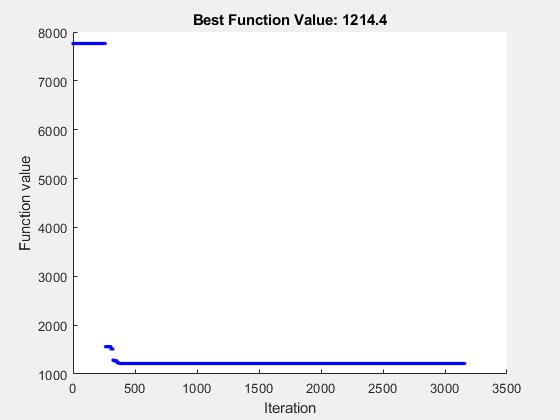

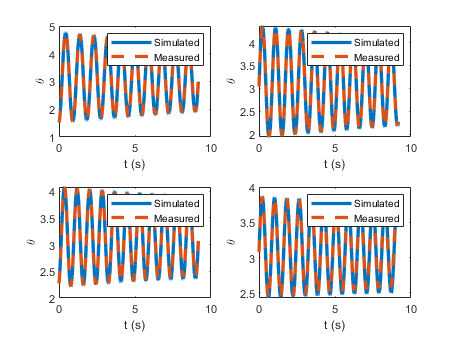

Optimization terminated: change in best function value less than options.FunctionTolerance.


% Pass fixed parameters to objfun
objfun = @(EstimationParameters)ObjectiveFuntion_SinglePendulumParameterEstimation(EstimationParameters,...
    dt,Y_id);

% Set nondefault solver options
options = optimoptions("simulannealbnd","Display","iter","PlotFcn",...
    "saplotbestf");

% Solve
[EstimatedParameters,l2normError] = simulannealbnd(objfun,EstimationParameters0,lb,...
    up,options);


% Clear variables
clearvars objfun options

## Results

`We will save the parameter estimation result "EstimatedParameters" into a mat file called "EstimatedParameters.mat"`

EstimatedParameters

EstimatedParameters =     0.1469    0.1477    0.0001    0.0002    9.8100


if length(EstimationParameters0)==4
    EstimatedParameters=[EstimatedParameters g];
end
%save('EstimatedParameters_SinglePendulum.mat','EstimatedParameters');

## Now, Validate the Estimated Parameters Using Validation Data

Y_es=cell(length(Y_vad),1);

for i=1:length(Y_vad)
    % First determine the simulation time
    tspan=0:dt:length(Y_vad{i})*dt-dt;
    
    % Next, determine the initial condition used for simulation, the first
    % data will be used as initial condition
    y0=Y_vad{i}(:,1);
    
    % Now, run the simulation and simulate the system
    if length(EstimationParameters0)==5
        [~,y_es]=ode15s(@(t,y)SinglePendulumODE(t,y,EstimationParameters0(1),EstimationParameters0(2),...
            EstimationParameters0(3),EstimationParameters0(4),EstimationParameters0(5)),tspan,y0);
    else
        [~,y_es]=ode15s(@(t,y)SinglePendulumODE(t,y,EstimationParameters0(1),EstimationParameters0(2)...
            ,EstimationParameters0(3),EstimationParameters0(4),g),tspan,y0);
    end
    
    % Now store the simulated data into an array
    Y_es{i}=y_es';
    
    % Now calculate the difference (l2 norm) of the simualted data and measrued data
    l2VadNormError=norm(Y_vad{i}-Y_es{i})^2
end

l2VadNormError = 994.7513

l2VadNormError = 965.4460

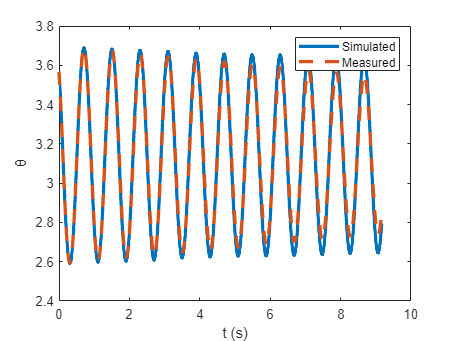

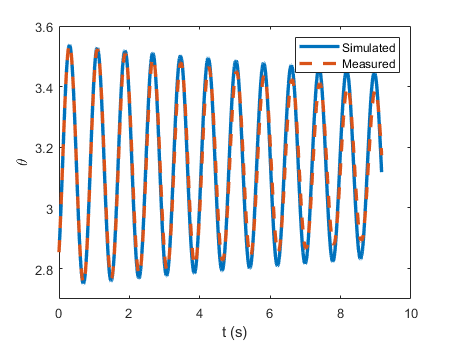


close all
for i=1:length(Y_vad)
    figure(i)
    plot(0:dt:length(Y_vad{i})*dt-dt,Y_es{i}(1,:),'LineWidth',2.5)
    hold on
    plot(0:dt:length(Y_vad{i})*dt-dt,Y_vad{i}(1,:),'LineWidth',2.5,'LineStyle','--')
    legend("Simulated","Measured")
    xlabel("t (s)")
    ylabel("\theta")
end